# Walelet Power Spectrum with non stationary periodicities

In this simple script we calculate the Wavelet Power Spectrum using Torrence and Compo (1998) algorithm.

***Author: Annalisa Molini***

***Last updated: Oct 18,2022***

## Signal Sampling and Duration

Let us first define the sampling and duration of our synthetic signal:

Fs = 1000;            % Sampling frequency [in Hz] 
T = 1/Fs;             % Sampling period [in seconds]   
L = 1500;             % Length of signal [Number of samples]
t = (0:L-1)*T;        % Time vector [in s]

The next step is to generate the synthetic signal using the time vector t. We want to create a signal containing a sinusoid of amplitude A1 and frequency f1 and one of amplitude A2 and frequency f2, enbedded in white noise of pre-assigned variance s2n:

A1=2;               % Amplitude [in a.u.]
f1=40;              % Frequency [in Hz]
A2=2;               % Amplitude [in a.u.]
f2=80;             % Frequency [in Hz]
A3=2;               % Amplitude [in a.u.]
f3=180;             % Frequency [in Hz]
s2n=4;

t1=t;
t1(L/2:end)=0;
t2=t;
t2(1:L/2-1)=0;
t3=t;
t3(L/4:2*L/4)=0;

% Generate sinusoids
S1 = A1*sin(2*pi*f1*t1);
S2=A2*sin(2*pi*f2*t2);
S3=A3*sin(2*pi*f3*t3);
S=S1+S2+S3;
% Generate White Noise
Wn= sqrt(s2n)*randn(size(t));

% Generate the final signal as a sum of the two above
X = S + Wn;

Let us now plot the noisy signal in the time domain and compare it with the 'periodic' original signal:

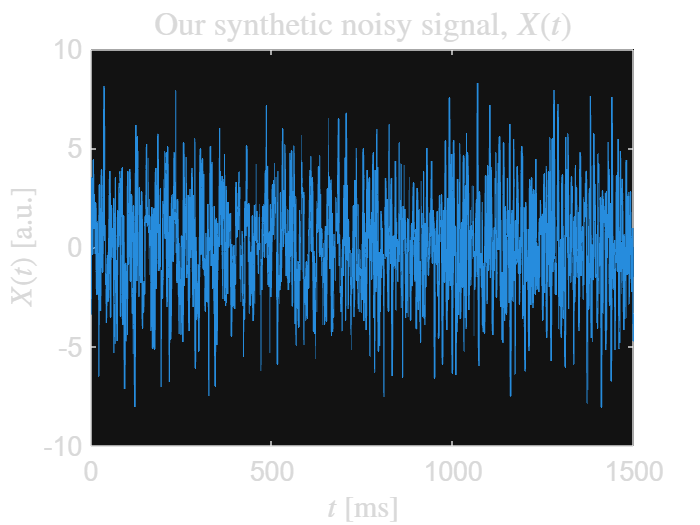

figure;
sfont=16;
h1=plot(1000*t,X);
set(h1,'linewidth', 1);
set(gca,'FontSize',16);

% Axex labels
xlabel("$t$ [ms]","FontSize",18,'Interpreter','latex');
ylabel("$X(t)$ [a.u.]","FontSize",18,'Interpreter','latex');
title("Our synthetic noisy signal, $X(t)$","FontSize",20,'Interpreter','latex');

hold off;

## Wavelet spectrum

Let us now try to use T&C code to generate the wavelet power spectrum of our signal:

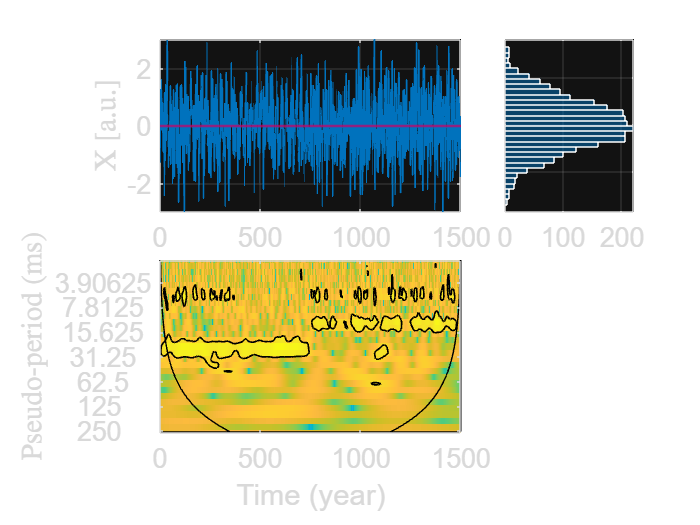

dummyvar=X;

variance = std(dummyvar)^2;
dummyvar = (dummyvar - mean(dummyvar))/sqrt(variance) ;

n = length(dummyvar);
dt = T ;
time=t*1000;% time array
xlim = [0,1000*L/Fs];  % plotting range
pad = 1;      % pad the time series with zeroes (recommended)
dj = 0.25;    % this will do 4 sub-octaves per octave
s0 = 2*dt;    % this says start at a scale of 6 months
j1 = 7/dj;    % this says do 7 powers-of-two with dj sub-octaves each
lag1 = 0.0;  % lag-1 autocorrelation for red noise background
mother = 'Morlet';

% Wavelet transform:
[wave,period,scale,coi] = wavelet(dummyvar,dt,pad,dj,s0,j1,mother);
power = (abs(wave)).^2 ;        % compute wavelet power spectrum

% Significance levels: (variance=1 for the normalized SST)
[signif,fft_theor] = wave_signif(1.0,dt,scale,0,lag1,-1,-1,mother);
sig95 = (signif')*(ones(1,n));  % expand signif --> (J+1)x(N) array
sig95 = power ./ sig95;         % where ratio > 1, power is significant

% Global wavelet spectrum & significance levels:
global_ws = variance*(sum(power')/n);   % time-average over all times
dof = n - scale;  % the -scale corrects for padding at edges
global_signif = wave_signif(variance,dt,scale,1,lag1,-1,dof,mother);

% % Scale-average between El Nino periods of 2--8 years
% avg = find((scale >= 8) & (scale < 16));
% Cdelta = 0.776;   % this is for the MORLET wavelet
% scale_avg = (scale')*(ones(1,n));  % expand scale --> (J+1)x(N) array
% scale_avg = power ./ scale_avg;   % [Eqn(24)]
% scale_avg = variance*dj*dt/Cdelta*sum(scale_avg(avg,:));   % [Eqn(24)]
% scaleavg_signif = wave_signif(variance,dt,scale,2,lag1,-1,[2,7.9],mother);

%whos

%------------------------------------------------------ Plotting

%--- Plot time series
%subplot('position',[0.1 0.75 0.65 0.2])
figure;
tiledlayout(2,3,'TileSpacing','compact');
nexttile([1,2]);
plot(time,dummyvar,'linewidth',1,'Color','#0072BD');
set(gca,'XLim',xlim(:),'FontSize',sfont);
%xlabel('Time (ms)')
ylabel('X [a.u.]','FontSize',sfont+2,'Interpreter','latex');
yl=yline(mean(dummyvar),'linewidth',1.5,'linestyle','-');
yl.Color = [.80 0 .40];
grid on;
hold off

% SL Hist
nexttile
nb=30;
h1=histogram(X,nb,'Normalization','countdensity','Orientation','horizontal');
set(gca,'FontSize',sfont,'YTickLabel',[]);
set(h1,'linewidth', .5,'FaceColor','#0072BD','EdgeColor','w','FaceAlpha',.5);
grid on;

%--- Contour plot wavelet power spectrum
nexttile([1,2]);
levels = [0.0625,0.125,0.25,0.5,1,2,4,8,16] ;
Yticks = 2.^(fix(log2(min(period))):fix(log2(max(period))));
%contour(time,log2(period),log2(power),log2(levels));  %*** or use 'contourfill'
imagesc(time,log2(period),log2(power));  %*** uncomment for 'image' plot
xlabel('Time (year)')
ylabel('Pseudo-period (ms)','FontSize',sfont+2,'Interpreter','latex')
set(gca,'XLim',xlim(:),'FontSize',sfont)
set(gca,'YLim',log2([min(period),max(period)]), ...
	'YDir','reverse', ...
	'YTick',log2(Yticks(:)), ...
	'YTickLabel',Yticks*1000)
% 95% significance contour, levels at -99 (fake) and 1 (95% signif)
% hold on
% contour(time,log2(period),sig95,[-99,1],'k');

hold on
    [cs,h] = contour(time,log2(period),sig95,[-99,1],'k');     
    hold on
    set(h,'linewidth',1);    
    hold on;
% hold on
% cone-of-influence, anything "below" is dubious
%plot(time,log2(coi),'k')
    ts = time;
    coi_area = [max(scale) coi max(scale) max(scale)];
    ts_area = [ts(1) ts ts(length(ts)) ts(1)];
    L = plot(ts_area,log2(coi_area),'k'); set(L,'linewidth',.3); hold on

    hatch(L,45,'k','-',5,.3); hold on

Unrecognized function or variable 'hatch'.

    hatch(L,135,'k','-',5,.3); hold on

hold off

%--- Plot global wavelet spectrum
nexttile;
plot(global_ws,log2(period),'linewidth',1,'Color','#0072BD')
hold on
plot(global_signif,log2(period),'--')
hold off
xlabel('$S_{SL}$ (a.u.$^2$)','FontSize',sfont+2,'Interpreter','latex')
set(gca,'YLim',log2([min(period),max(period)]), ...
	'YDir','reverse', ...
	'YTick',log2(Yticks(:)), ...
	'YTickLabel','')
set(gca,'XLim',[0,1.25*max(global_ws)],'FontSize',sfont);
grid on;

## Anderson-Darling Test for Gaussianity

[hMR,pvln,adstatln,cvln] = adtest(X,'MCTol',0.01,'Alpha',0.05)

## And the Bias Corrected spectrum

% Rectification of the bias in the Wavelet power spectrum with the data set
% (Nino3.dat) given by Torrence and Compo (1998).  This code is modified
% from wavetest.m, the example script provided by Torrence and Compo
% (1998), to demonstrate how to rectify the bias in wavelet power spectrum.
% This code generates Figure 4 of Liu et al. (2007).
%
% Yonggang Liu, 2006.4.12
%
% E-mail:  yliu18@gmail.com
% http://ocgweb.marine.usf.edu/~liu/wavelet.html
%
% References:
%
% Liu, Y., X.S. Liang, and R.H. Weisberg, 2007: Rectification of the bias
% in the wavelet power spectrum. Journal of Atmospheric and Oceanic 
% Technology, 24(12), 2093-2102.
% 
% Torrence, C., and G. P. Compo, 1998: A practical guide to wavelet 
% analysis. Bull. Amer. Meteor. Soc., 79, 6178.
%========================================================================
% Here starts with the original file header:


%WAVETEST Example Matlab script for WAVELET, using NINO3 SST dataset
%
% See "http://paos.colorado.edu/research/wavelets/"
% Written January 1998 by C. Torrence
%
% Modified Oct 1999, changed Global Wavelet Spectrum (GWS) to be sideways,
%   changed all "log" to "log2", changed logarithmic axis on GWS to
%   a normal axis.


%==================  Bias rectification start  =========================
 %--- divided by scales:
 powers=zeros(size(power,1),size(power,2));
   for k=1:length(scale)
     powers(k,:) = power(k,:)/scale(k);
   end
   global_wss = global_ws./scale;
  c = powers;
  c = c(:);
%==================  Bias rectification end  =========================
  

%--- Contour plot wavelet power spectrum
   figure;
   tiledlayout(2,3,'TileSpacing','compact');
   nexttile([1 2]);
    levelss = 2.^[-6:2] ;
    Yticks = 2.^(fix(log2(min(period))):fix(log2(max(period))));
    contour(time,log2(period),log2(powers),log2(levelss));  
    caxis([log2(levelss(1)), log2(levelss(end))]);

    xlabel('Time (ms)','fontsize',sfont+2,'Interpreter','latex')
    ylabel('Pseudo-period (ms)','FontSize',sfont+2,'Interpreter','latex')
    set(gca,'XLim',xlim(:),'FontSize',sfont) 

    
    set(gca,'XLim',xlim(:))
    set(gca,'YLim',log2([min(period),max(period)]), ...
	'YDir','reverse', ...
	'YTick',log2(Yticks(:)), ...
	'YTickLabel',1000*Yticks)
   % 95% significance contour, levels at -99 (fake) and 1 (95% signif)
    hold on
    [cs,h] = contour(time,log2(period),sig95,[-99,1],'k');     
    hold on
    set(h,'linewidth',1);    
    hold on;

   % cone-of-influence, anything "below" is dubious
    % plot(time,log2(coi),'k'); hold off
    L = plot(ts_area,log2(coi_area),'k'); set(L,'linewidth',.3); hold on
    hatch(L,45,'k','-',5,.3); hold on
    hatch(L,135,'k','-',5,.3); hold on

 %--- Plot global wavelet spectrum
     nexttile();
    plot(global_wss,log2(period),'linewidth',1,'Color','#0072BD')
    hold on
   %hold on
   %plot(global_signif,log2(period),'--')
   %hold off
    set(gca,'YLim',log2([min(period),max(period)]), ...
	'YDir','reverse', ...
	'YTick',log2(Yticks(:)), ...
	'YTickLabel','')
    set(gca,'XLim',[0,1.25*max(global_wss)],'fontsize',sfont)
   %% xlabel('Global')
    xlabel('$S_{SL}$ (a.u.$^2$)','FontSize',sfont+2,'Interpreter','latex')

print -djpeg wavelet_test_ElNino33.jp